# Alejandro Stawsky, Math 104C HW 5, June 6, 2018

- Let $T\left(\alpha \right)$ be the same as in the HW prompt, i.e. an $n\text{ }\mathrm{x}\text{ }n$ matrix such that ${\left(T\left(\alpha \right)\right)}_{i,i} =\alpha ,{\left(T\left(\alpha \right)\right)}_{i,i-1} ={\left(T\left(\alpha \right)\right)}_{i-1,i} =-1\ldotp$ Let $V={\left\lbrack V_1 \text{ }\ldotp \ldotp \ldotp V_n \right\rbrack }^T$ and $\lambda$ and eigenvalue. Then $T\left(\alpha \right)V=\lambda V\Rightarrow {\left(T\left(\alpha \right)V\right)}_j =-V_{j-1} +\alpha V_j -V_{j+1} =\lambda V_j \Rightarrow -V_{j-1} +\left(\alpha -\lambda \right)V_j -V_{j+1} =0$. Setting $\xi^j =V_j$, we get something like the characteristic polynomial for zero-stability, $\rho \left(\xi \right)=-\xi^{j-1} +\left(\alpha -\lambda \right)\xi^j -\xi^{j+1} =0$. Suppose that $\xi_1$ and $\xi_2$ are hte roots of the characteristic polynomial. We then get that $V_j =c_1 \xi_1 +c_2 \xi_2$ with constants $c_1 ,c_2$. In order for the notation to make sense $V_0 =0\Rightarrow c_1 +c_2 =0\Rightarrow {V_j =\text{ }c}_1 \left(\xi_1^j -\xi_2^j \right)=c\left(\xi_1^j -\xi_2^j \right)$ and also, $V_{n+1} =0\Rightarrow c\left(\xi_1^{n+1} -\xi_2^{n+1} \right)=1$. Since $V\not= 0$ by construction of an eigenvector, $c\not= 0$ and $\left(\xi_1^{n+1} -\xi_2^{n+1} \right)=0\Rightarrow {\left(\frac{\xi_1 }{\xi_2 }\right)}^{n+1} =1$. From a general, homogeneous quadratic equation ${\mathit{ax}}^2 +\mathit{bx}+c=0$, we get the two roots from the quadratic formula: $x_1 =\frac{-b+\sqrt{b^2 -4\mathrm{ac}}}{2a}$ and $x_2 =\frac{-b-\sqrt{b^2 -4\mathrm{ac}}}{2a}$, which imply $x_1 +x_2 =\frac{-b}{a}$ and $x_1 x_2 =\frac{c}{a}$. Since $\rho \left(\xi \right)$ is a quadratic equation, $a=c=-1$ and $b=\left(\alpha -\lambda \right)\Rightarrow {\xi_1 \xi_2 =1\Rightarrow \text{ }\xi }_2 =\frac{1}{\xi_1 }\Rightarrow {\left(\frac{\xi_1 }{\xi_2 }\right)}^{n+1} ={\left(\xi_1^2 \right)}^{n+1} =\xi_1^{2n+2} =1$. This means that the first root of the characteristic polynomial can be any $2n+2$ root of unity, i.e. $\xi_{1,p} =e^{2\pi i\frac{p}{2n+2}}$ for $p=0:2n+1$. However, we can simplify this farther: $\xi_{1,p} =e^{2\pi i\frac{p}{2n+2}} =e^{\pi i\frac{p}{n+1}}$ for $p=0:n$. However, notice that if $p=0$, then $\xi_{1,0} =1$ and $\xi_{2,p} =e^{-\pi i\frac{p}{n+1}} \Rightarrow \xi_{2,0} =1$, meaning that $V_j =c\left(\xi_{1,0}^j -\xi_{2,0}^j \right)=0\text{ }\forall j=0:n$, which is not possible since $V$ is an eigenvector. For every other value of $p$, $\xi_{2,p} \not= \xi_{1,p}$. In addition to this, $\xi_{1,p}$ and $\xi_{2,p}$ are complex conjugates and together they make up all the suitable roots of unity for $p=1:n$. We then have $n$ eigenvalues as expected, $\lambda_p$ for $p=1:n$. Because $x_1 +x_2 =\frac{-b}{a}$, we get a formulation for all the eigenvalues of $T\left(\alpha \right)$: $\xi_{1,p} +\xi_{2,p} =e^{\pi i\frac{p}{n+1}} +e^{-\pi i\frac{p}{n+1}} =2\mathrm{cos}\left(\frac{p\pi }{n+1}\right)=\alpha -\lambda_p \Rightarrow \lambda_p =\alpha -2\mathrm{cos}\left(\frac{p\pi }{n+1}\right)$. Using this we get a formulation for all the eigenvectors of $T\left(\alpha \right)$: $V_j^p =\left(\xi_{1,p}^j -\xi_{2,p}^j \right)=\left(e^{\pi i\frac{p}{n+1}} -e^{-\pi i\frac{p}{n+1}} \right)=\left(2i\sin \left(\frac{\text{pj}\pi }{n+1}\right)\right)$ where $V^p$ is the eigenvector corresponding to $\lambda_p$. For all choices of $\alpha$, $T\left(\alpha \right)$ is a symmetric matrix. This means that $T\left(\alpha \right)$ is positive definite iff $\lambda_p >0\text{ }\forall p=1:n\Rightarrow \alpha >2\cos \left(\frac{\pi }{n+1}\right)$. To be safe one can make $\alpha \ge 2>2\cos \left(\frac{p\pi }{n+1}\right)$ because $\mathrm{cos}\left(x\right)\le 1$.

- $\left\lbrace \begin{array}{cc}
-\mathit{u''}\left(x\right)=9\mathit{sin}\left(3x\right)-6x,\text{ } & x\in \left(0,\pi \right)\\
u\left(0\right)=0,\text{ } & u\left(\pi \right)=\pi^3 
\end{array}\right.$   with the exact solution $u\left(x\right)=\mathit{sin}\left(3x\right)+x^3$.

                (a)+(b) implement Thomas algorithm to and graph the loglog plots of the errors in the max and 2-norm with comparison to the second order slope line on $n=10,20,30,\ldotp \ldotp \ldotp ,100$.

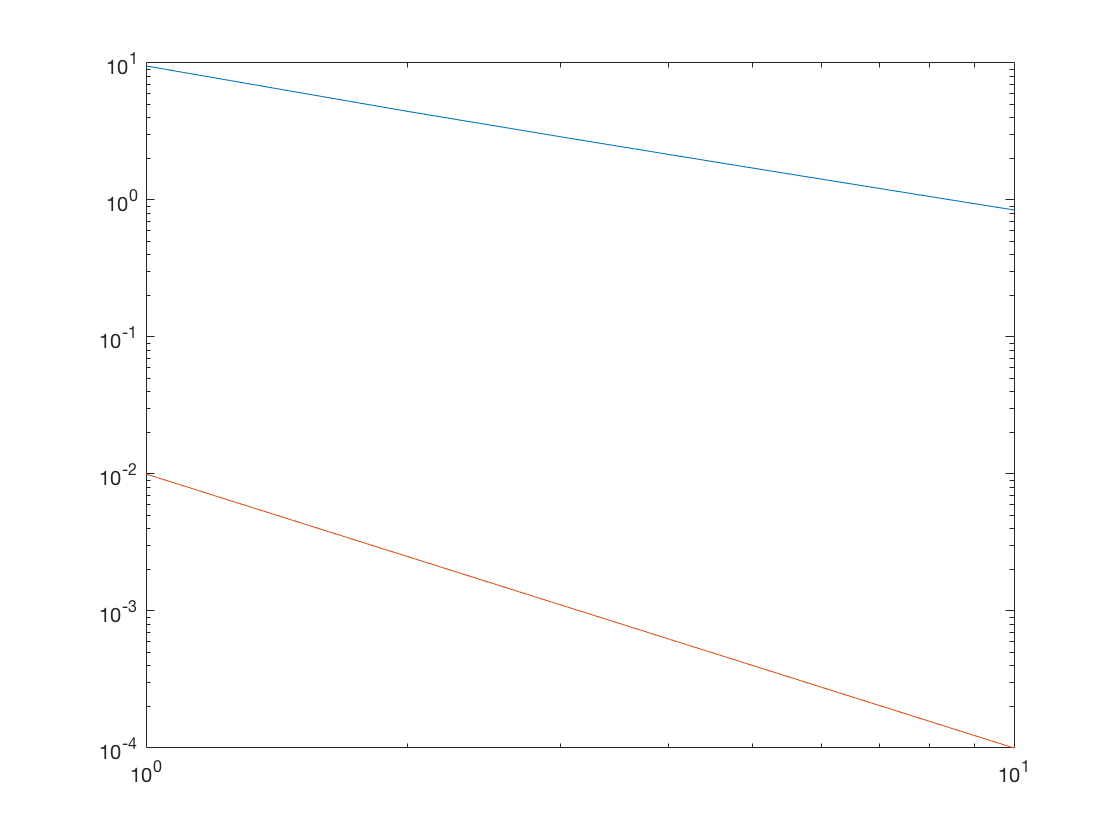


% solving for all values of n and getting their respective errors
for i=1:10
    [A,F,TruVals,X,h]=CentralDiff(10*i);
    U=Thomas(A,F);
    inftyerror(i)=max(abs(U-TruVals));
    twoerror(i)=sqrt(h*sum((U-TruVals).^2));
    slopeline(i)=1/((10*i)^2);
end

% plotting the errors
loglog(1:10,inftyerror);
hold on
loglog(1:10,slopeline);
hold off

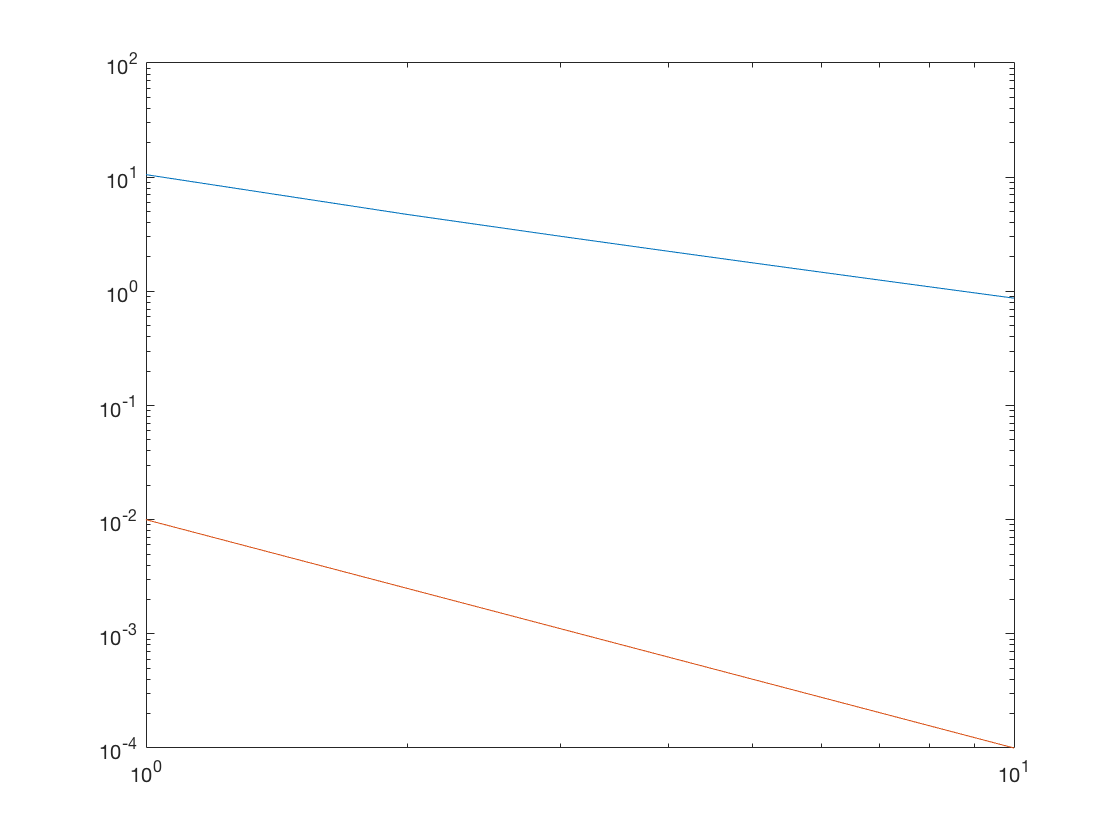


loglog(1:10,twoerror);
hold on
loglog(1:10,slopeline);

function [A,F,TruVals,X,h] = CentralDiff(n)

% setting the second derivative and the exact solution
f=@(x) 9*sin(3*x)-6*x;
u=@(x) sin(3*x)+x^3;

% n is the amount of grid points
h=pi/(n-1);

for i=1:n-1
    
    % making the tridiagonal matrix A, (n-1)x(n-1) matrix
    A(i,i)=2*(1/h^2);
    if i~=1
        A(i,i-1)=-1*(1/h^2);
    end
    if i~=n-1
        A(i,i+1)=-1*(1/h^2);
    end
    
    % setting the grid points
    X(i)=i*h;
    
    % making the F vector
    if i==n-1
        F(i)=f(X(i))+pi^3/h^2;
    else
        F(i)=f(X(i));
    end
    
    % making the vector of true values
    TruVals(i)=u(X(i));
    
end

end




function [U] = Thomas(A,F)

[n,~]=size(A);

for i=1:n-1
    
    % The new coeffiecients
    if i==1
        C(i)=A(i,i+1)/A(i,i);
        D(i)=F(i)/A(i,i);
    else
        C(i)=A(i,i+1)/(A(i,i)-A(i,i-1)*C(i-1));
        D(i)=(F(i)-A(i,i-1)*D(i-1))/(A(i,i)-A(i,i-1)*C(i-1));
    end
    
end

D(n)=(F(n)-A(n,n-1)*D(n-1))/(A(n,n)-A(n,n-1)*C(n-1));

% Back sub to solve for U
U(n)=D(n);

for i=n-1:-1:1
    U(i)=D(i)-C(i)*U(i+1);
end

end

